# 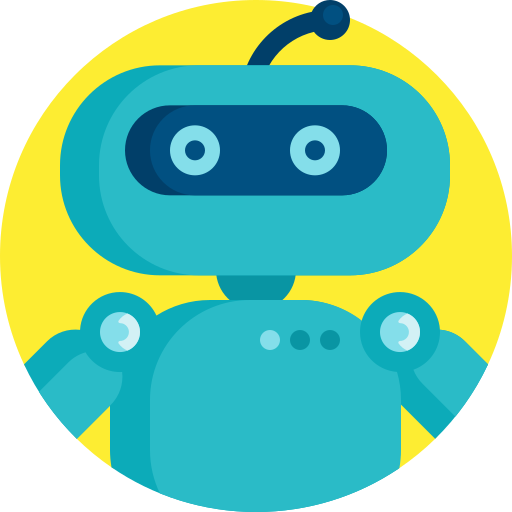

# **MEC4127F: Introduction to Robotics**

# Chapter 8: Control design for wheeled robots

## 8.1 Introduction

This Chapter will focus on introductory nonlinear control methods that relate to a differentially-steered mobile robot. Generalised concepts will also be covered that apply to any type of rigid-body platform, which will be useful in later chapters when tackling quadcopter control design. 

The motion control problem for wheeled robots often only considers the kinematic model, ignoring the underlying dynamics of the platform. In this way, the translational and angular velocities of the robot in $\{B\}$ are treated as the virtualised controller commands. The assumption here is that a low-level controller exists that commands wheel torques and can regulate the translational and angular velocities with sufficient bandwidth and precision. In other words, the wheel speed control is sufficiently fast, relative to the mobility of the wheeled robot, such that it can be assumed instantaneous.

## 8.2 Body-frame position error 

In order to incorporate feedback control on our mobile robot, we first need to define the error that will drive our control loop. In the case of position control we require a position error. Because we are assuming that we can directly control translational and angular velocity in $\{B\}$, it makes sense to define our position error in $\{B\}$ — where the control action is directly taking place. 

### 8.2.1 Position error in SE(3)

With reference to Figure 8.1, we will start by describing the current position of our robot in $\{W\}$ as


$${^W{\bf p}}={^W{\bf t}_B},$$


which describes, as before, the location of the frame $\{B\}$ origin with respect to $\{W\}$. 

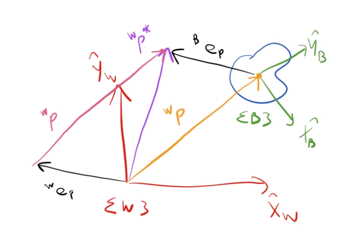

**Figure 8.1:** Representation of three key frames for control design:$\{W\}$, $\{B\}$, and $\{D\}$.

The desired reference is indicated by $\{D\}$, which describes how we ultimately want our robot to be configured. The desired position therefore follows as


$${^W{\bf p}^*}={^W{\bf t}_D}.$$


The position error in $\{W\}$ is then given by


$$\begin{array}{cc}{ ^W{\mathbf e}}_p = { ^W{\mathbf p}^\ast} - { ^W{\mathbf p}}.\end{array}$$


We unfortunately cannot directly use the error vector above for control, as the actuation of the robot as a result of the wheel speeds takes place in $\{B\}$. Instead, we will re-represent vector ${^W{\bf p}^*}={^W{\bf t}_D}$ with respect to $\{B\}$, namely, ${^B{\bf p}^*}$, which describes the incremental position change required in $\{B\}$ to move the robot to the desired position. Based on **Chapter 2**, we can determine this quantity using our generalised vector mapping equation:


$$\begin{array}{ll}
{^B{\bf p}^*}
&=&{^B{\bf R}_W}{^W{\bf p}^*}+{^B{\bf t}_W},\\
&=&{^B{\bf R}_W}{^W{\bf p}^*}-{^B{\bf R}_W}{^W{\bf t}_B},\\
&=&{^B{\bf R}_W}\left({^W{\bf p}^*}-{^W{\bf t}_B}\right),\\
&=&{^B{\bf R}_W}\left({^W{\bf p}^*}-{^W{\bf p}}\right),\\
&=&{^B{\bf R}_W}{^W{\bf e}_p},\\
&=&{^B{\bf e}_p}.
\end{array}$$


The quantity above can be thought of both as a desired position in $\{B\}$, ${^B{\bf p}^*}$, or a position error in $\{B\}$, ${^B{\bf e}_p}$, as the current position in $\{B\}$ will always be equal to zero — ${^B{\bf p}}={{\bf 0}}.$ In SE(3), ${^W{\bf R}_B}\in \text{S0}(3)$, implying that orientation representation must be chosen, with exponential coordinates and quaternions serving as popular and reliable choices.

Note that we could have also obtained the result above by mapping the world-frame position error through our rotation matrix describing $\{W\}$ with respect to $\{B\}$, namely


$$\begin{array}{cc}{ ^B{\mathbf e}}_p = {^B {\mathbf R}_W} { ^W{\mathbf e}}_p,\end{array}$$


where ${^W{\bf e}_p}\in \mathbb{R}^3$. We do not need to account for the translation between the two frame origins as we are interested in the *differential* behaviour of our system. Error signal ${ ^B{\mathbf e}}_p$ gives an indication of how the robot needs to make corrections in $\{B\}$, which is where actuation is directly acting. It is important to highlight that we cannot perform arbitrary position control if we do not know the current orientation of the robot. By extension, inaccuracies in our orientation estimate will negatively affect our position controller, by virtue of an incorrect position error.

Once we have formulated the rectilinear tracking problem in the actuator space, we can design a control scheme that minimises this error. Successfully enforcing  ${ ^B{\mathbf e}}_p \rightarrow {\mathbf 0}$ implies that  ${ ^W{\mathbf p}}={ ^W{\mathbf p}^\ast}$, which is easy to verify based on the equations above. In other words, our robot position in the task space will have reached its desired location. The type of controller used will vary depending on the particular platform, but the archetypal *PID* control structure is generally used and adapted where appropriate — we can "disable" elements of a PID controller to reduce it to a proportional controller, proportional-plus-integral controller, or proportional-derivative controller — which comes down to the specific robotic use case. 

### 8.2.2 Position error in SE(2)

When operating on a plane, such as is the case for wheeled robots, the rotation matrix is described by


$$\begin{array}{cc}{^W{\mathbf R}_B} = \left[\begin{array}{cccccccc}    \cos{\psi} & -\sin{\psi} \\    \sin{\psi} & \cos{\psi} \\ \end{array}\right]\in \text{SO}(2), \end{array}$$


where $\psi$ uniquely defines the orientation of the robot. By extension, the position error will be a two-vector made up by


$$\begin{array}{cc}{ ^B{\mathbf e}}_p = {^B {\mathbf R}_W} { ^W{\mathbf e}}_p\in \mathbb{R}^2.\end{array}$$


#### Example: Position error on a plane

The code block generates a visualisation for a wheeled robot on plane. The position error in $\{B\}$ is also provided, based on the equation above. 

You should notice that:

- The position error in $\{W\}$ is not affected by the current orientation.

- The position error in $\{B\}$ is a function of the current orientation, but not of the orientation of $\{D\}$.

clear

psi =180*pi/180;

figure(1),clf
%{D}
t_d2w = [0 10 0];
q_d2w = [cos(pi/4) 0 0 sin(pi/4)];
plotTransforms(t_d2w, q_d2w, "Parent", gca, "View","2D", "FrameSize", 2,"FrameAxisLabels","on","FrameLabel","D");
%{B}
t_b2w = [10 10 0];
q_b2w = [cos(psi/2) 0 0 sin(psi/2)];
plotTransforms(t_b2w, q_b2w, "MeshFilePath", "groundvehicle.stl", "Parent", gca, "View","2D", "FrameSize", 2,"FrameAxisLabels","on","FrameLabel","B");
%{W}
plotTransforms([0 0 0], [1 0 0 0], "Parent", gca, "View","2D", "FrameSize", 2,"FrameAxisLabels","on","FrameLabel","W");
axis([-5 15 -5 15]),grid on
view(2)

R = [cos(psi) -sin(psi);
     sin(psi)  cos(psi)];
e_w = t_d2w(1:2)'-t_b2w(1:2)';
e_b = R'*e_w;

title(['${^B{\bf e}_p}=[$',num2str(e_b(1)),'  ',num2str(e_b(2)),'$]^T$'],Interpreter="latex")

## 8.3 Body-frame orientation error

Correcting the orientation of a generic platform follows a similar thinking as that of the position error, albeit with some additional intricacies. We will consider two approaches to generating a description of the body-frame orientation error:

- Rotation matrices

- Quaternions

When dealing with robotic platforms that can move outside of a fixed plane (e.g. a quadcopter), simply taking the difference between the desired and actual Euler angle vectors is not an appropriate description of the orientation error in $\{B\}$ — where the control action is going to take place. We can still try map this world-frame Euler error to the body-frame using a special matrix mapping, but the sequential nature of Euler angles is not in line with our rigid bodies are expected to behave in general. For that reason, we will consider other approaches. Note that the Euler error approach is suitable when the angle errors are sufficiently small.

### 8.3.1 Rotation matrix formulation 

This subsection will cover the generalised case of operating in SO(3), but without loss of generality, this method can always be reduced to SO(2). We start by describing the orientation of our body-frame with respect to the world-frame, using  ${^W{\mathbf R}_B}$, where our matrix is parameterised by quaternions, exponential coordinates, or some other representation. We can additionally describe a *desired* orientation using  ${^W{\mathbf R}^*_B}={^W{\mathbf R}_D}$ . With reference to Figure 8.2, this desired orientation implies that we are introducing a third reference frame that describes how we would like our body-frame to be oriented relative to $\{W\}$.

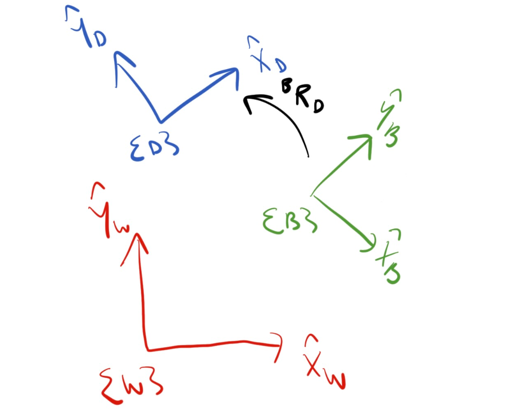

**Figure 8.2:** Depiction of the three fundamental reference frames when resolving orientation error.
 

If our desired orientation is different to our current orientation (${^W{\mathbf R}_B}\neq{^W{\mathbf R}_D}$), we will require some kind of adjustment in order to orchestrate the correct rotation, whereas if the two are aligned (${^W{\mathbf R}_B}={^W{\mathbf R}_D}$), we do not need to do anything. In general, we would like to find a desired orientation that is described in $\{B\}$, which tells us how the body frame needs to alter itself to meet our target configuration. Pre-multiplying  ${^W{\mathbf R}_D}$ by  ${^W{\mathbf R}_B^T}={^B{\mathbf R}_W}$ , we can map the desired orientation in $\{W\}$ to the desired orientation in $\{B\}$, which is given by 


$$\begin{array}{cc}{^B{\mathbf R}_D} = {^B{\mathbf R}_W}{^W{\mathbf R}_D}. \end{array}$$


Note again how the sub- and superscripts cancel out to yield the resulting rotation matrix. Matrix ${^B{\mathbf R}_D}$ gives an indication of how the platform orientation, described in the body-frame, should reorient itself in order to meet the world-frame objective of  ${^W{\mathbf R}^*_B}={^W{\mathbf R}_D}$ , and also can be thought of as the encoded orientation error, as the body-frame orientation will always remain null. 

We can decode the resulting rotation matrix $\begin{array}{cc}{^B{\mathbf R}_D}  \end{array}$ to obtain a vector description of the error, which could take the form of exponential coordinates or Euler error. This 3-vector of angles can then be used to inform the robot platform of how to correct its orientation about the three axes in $\{B\}$.

#### 8.3.1.1 Euler error

Assuming the body-frame Euler errors are of interest, one can extract this information from 


$$\begin{array}{cc}^B{\mathbf R}_D = \left[\begin{array}{cccccccc}    r_{11} & r_{12} & r_{13} \\    r_{21} & r_{22} & r_{23} \\    r_{31} & r_{32} & r_{33}    \\ \end{array}\right]=    \left[\begin{array}{cccccccc}    \cos{\psi_e}\cos{\theta_e} & \cos{\psi_e}\sin{\theta_e}\sin{\phi_e}-\cos{\phi_e}\sin{\psi_e} & \sin{\psi_e}\sin{\phi_e}+\cos{\psi_e}\cos{\phi_e}\sin{\theta_e}\\    \cos{\theta_e}\sin{\psi_e} & \cos{\psi_e}\cos{\phi_e}+\sin{\psi_e}\sin{\theta_e}\sin{\phi_e} & \cos{\phi_e}\sin{\psi_e}\sin{\theta_e}-\cos{\psi_e}\sin{\phi_e} \\    -\sin{\theta_e} & \cos{\theta_e}\sin{\phi_e} & \cos{\phi_e}\cos{\theta_e}    \\ \end{array}\right]    \end{array}$$


using


$$\begin{array}{cc}\phi_e = \arctan(\frac{r_{32}}{r_{33}})\end{array},$$



$$\begin{array}{cc}\theta_e = -\arcsin{r_{31},\end{array}$$



$$\begin{array}{cc}\psi_e = \arctan(\frac{r_{21}}{r_{11}}).\end{array}$$


The nature of Euler angles is that three sequential rotations are required, so the robot would need to make corrections in three discrete rotations, instead of one single rotation. This presents issues if time or energy optimality are important to the functionality of the system. Additionally, if the system is conditionally stable, having to perform three discrete rotations may not be feasible. Having said that, one can treat the three distinct rotations as one combined rotation if the rotational angles are sufficiently small such that  ${^B{\mathbf R}_D}\approx {\mathbf I}$ . This would mean that our quantification of the body-frame correction required is not perfectly accurate, but rather approximately accurate. As previously touched on, motion control for rigid-body robots does not naturally take place in ordered sequences, but rather lends itself to instantaneous gross motions. Euler angles can still be used in control systems that make use of 3D rotations if the correct considerations are made — specifically, concerning the span of orientations that the system is expected to make use of. This makes the generalised Euler error largely unusable in a control sense (unless we intend to correct orientation errors in three disparate rotations, for example on a pan-tilt-roll camera). It would also not be possible to enforce this condition if the reference Euler angle experiences large step changes, as the Euler error would become large as a result of these steps. The Euler error formulation should therefore only be used for specific robotic platforms that experience small orientation errors (not to forget the other problem with singularities!). A fixed-wing airplane is a good example where using Euler errors is appropriate given the small angle behaviour during nominal flight conditions. This, however, would not be appropriate when speaking of fighter jets that perform aggressive and high angle-of-attack manoeuvres!

#### 8.3.1.2 Exponential coordinate error

Exponential coordinates are a natural way of expressing a rotation using the combination of a rotation vector and angle. Using our understanding of exponential coordinates, we can recover an error rotation vector from rotation matrix $\begin{array}{cc}{^B{\mathbf R}_D} = {^B{\mathbf R}_W}{^W{\mathbf R}_D} \end{array}$ using


$$\alpha_e=\cos^{-1}\left(\frac{1}{2}\left(\mathrm{tr}{^B{\bf R}_D}-1\right)\right),$$



$$\lfloor ^B\hat{\bf v}_e \rfloor = \frac{1}{2\sin{\alpha_e}}\left({^B{\bf R}_D}-{^B{\bf R}_D^T}\right).$$


Note that we are assuming $\alpha_e \neq \pi$ for sake of clarity. We can then combine the axis-angle form to give the exponential coordinates *exactly *describing rotation error as

${^B{\bf e}_o}=\alpha_e^B\hat{\bf v}_e$.

This vector indicates the rotational displacement in $\{B\}$ required to align $^W{\bf R}_B$ to $^W{\bf R}_D$. Unlike the caveats of Euler error vectors, the approach above exactly describes the orientation error in $\{B\}$. This is very useful when controlling the attitude of rigid-body systems. The benefit in specifying the corrective action in the form of a scaled rotation vector is that we can theoretically adjust our orientation in one smooth rotational movement, as opposed to three disjointed rotations. Note that in stark comparison to the Euler formulation, we are also not limited to only handling small angle errors — the angular error can be arbitrarily large without issue.

### 8.3.2 Quaternion error formulation 

The quaternion structure can be used instead of a rotation matrix, which is appealing for minimising numerical operations. Recall that the unit quaternion encodes the information related to a rotation vector. That is, a single rotation about a defined axis. This is appealing from a control point of view, as we can make orientation corrections simultaneously, without having to perform sequential operations or be subject to poor angle error approximations. For sake of convenience, the verbose quaternion structure is repeated below as 


$$\begin{array}{cc}{\mathbf q} = \left[\begin{array}{cc}    q_0 \\ q_x \\ q_y \\ q_z     \\ \end{array}\right] =    \left[\begin{array}{cc}    \cos{\frac{\alpha}{2}} \\ \sin{\frac{\alpha}{2}} \hat{\mathbf v}     \\ \end{array}\right] =     \left[\begin{array}{cc}    \cos{\frac{\alpha}{2}} \\     \sin{\frac{\alpha}{2}} v_x \\    \sin{\frac{\alpha}{2}} v_y \\    \sin{\frac{\alpha}{2}} v_z    \\ \end{array}\right].\\ \end{array}$$


Following a similar procedure as before, our quaternion representation of our robot orientation in$\{W\}$ is ${^W{\mathbf q}_B}$ , and our desired quaternion in $\{W\}$ is ${^W{\mathbf q}_D}$ . Analogous to $\begin{array}{cc}{^B{\mathbf R}_D} = {^B{\mathbf R}_W}{^W{\mathbf R}_D} \end{array}$, our error quaternion in $\{B\}$ is given by


$$\begin{array}{cc}{^B{\mathbf q}_D} = {^B{\mathbf q}_W} \otimes {^W{\mathbf q}_D}.\end{array}$$


The equation above is beneficial based on the low number of element-wise arithmetic operations relative to multiplying two rotation matrices, but we can also now extract the exponential coordinates embedded in our quaternion formulation. Given the standard unit quaternion structure, our error quaternion can be written as


$$\begin{array}{cc}{^B{\mathbf q}_D} =    \left[\begin{array}{cc}    \cos{\frac{\alpha_e}{2}} \\ \sin{\frac{\alpha_e}{2}} {^B\hat{\bf v}_e}     \\ \end{array}\right],\end{array}$$


where $\alpha_e$ corresponds to the rotation angle required to correct the orientation of the robot, and  $^B\hat{\bf v}_e$ refers to the rotation axis. Combined, the corresponding orientation error in $\{B\}$ is given by


$${^B{\bf e}_o}=\alpha_e^B\hat{\bf v}_e,$$


 which matches the result from the previous subsection when converting rotation matrices to exponential coordinate errors. 

### 8.3.3 Orientation error in SO(2)

The approaches presented above are crucial when controlling rigid-body robots, such as aerial vehicles and satellites. While the work presented above extends to all rotations in SO(3), there will be many cases when a robot is confined to a plane, in which case a single parameter, $\psi$ is required to describe orientation. As such, when operating in SO(2), the orientation error can be simply determined by taking the difference between a desired orientation, $\psi^*$, and the current orientation, $\psi$, which yields the orientation error of 


$${^W{e}_\psi}=\psi^*-\psi.$$


The rotation axis will always be perpendicular to the plane of operation, which implies that the world-frame description of orientation will be equivalent to the body-frame counterpart.

## 8.4 Point-to-point control 

We begin by considering point-to-point control, which refers to moving a robot, initially at rest, from an initial point in the task space to a final, static point, without consideration for the final orientation. The current position is described by ${^W{\bf p}}={^W{\bf t}_B}$, whereas the desired final position is ${^W{\bf p}^*}={^W{\bf t}_D}$.

### 8.4.1 Virtual control inputs

With reference to **Chapter 6**, the forward kinematics of the differentially-steered robot are repeated below for sake of convenience: 


$$\begin{array}{ll}\left[\begin{array}{cc}    ^W\dot{t}_x \\    ^W\dot{t}_y \\    \dot{\psi}    \\ \end{array}\right] &=&     \left[\begin{array}{cccccccc}    \cos{\psi} & -\sin{\psi} & 0\\    \sin{\psi} & \cos{\psi} & 0\\    0 & 0 & 1    \\ \end{array}\right]    \left[\begin{array}{cc}   v\\    0 \\    \dot\psi    \end{array}\right],\\

&=&  \left[\begin{array}{cc}    \frac{r_W}{2}\cos\psi & \frac{r_W}{2}\cos\psi\\    \frac{r_W}{2}\sin\psi & \frac{r_W}{2}\sin\psi \\  -\frac{r_W}{d} & \frac{r_W}{d}    \end{array}\right]
\left[\begin{array}{cc}    \dot\phi_L \\ \dot\phi_R   \end{array}\right],
\end{array}$$


where $v=\frac{r}{2}\left(\dot{\phi}_L+\dot{\phi}_R\right)$ and $\dot\psi=\frac{r}{d}\left( \dot{\phi}_R-\dot{\phi}_L \right)$. The actuator space is made up of $\{\dot\phi_L,\dot\phi_R\}$, which represents the low-level control of the wheeled robot. In other words, we can in theory choose at any time what we want the two wheel speeds to be. Because we know the mapping from $\{\dot\phi_L,\dot\phi_R\}$ to $\{v,\dot\psi\}$, we can abstract and simplify the problem by treating $v$ and $\dot\psi$ as our virtual control inputs. That is, they are not the signals that directly dictate the actuator states, but they are related by a mapping that remains constant. The idea here is that we can effectively decouple the two adjoined control problems (translation and rotation) into two independent problems by posing these virtual inputs in the correct way. Using the notation from Section 8.2, the virtualised kinematic model is given by


$$\left[\begin{array}{cc}    {\dot{p}_x^*} \\ {\dot{ p}^*_y}  \\ \dot\psi \end{array}\right]=\left[\begin{array}{cc}    v\cos\psi \\ v\sin\psi \\ \dot\psi \end{array}\right],$$
 

where ${\dot{p}_x^*}={\dot{t}_x^*}$ and ${\dot{p}_y^*}={\dot{t}_y^*}$. Note that at any time we can calculate the required wheel speeds using


$$\begin{array}{ll}\left[\begin{array}{cc}    \dot\phi_L \\   \dot\phi_R \end{array}\right] &=&     \frac{1}{r_W}\left[\begin{array}{cccccccc}    1 & -\frac{d}{2}\\    1 & \frac{d}{2} \end{array}\right]    \left[\begin{array}{cc}    v \\ \dot\psi    \end{array}\right],

\end{array}$$


which we would require when implementing our eventual control scheme.

### 8.4.2 Translational control

Point-to-point control considers the problem of driving a mobile robot from an initial known position, to a desired final position. In this configuration, no inherent trajectory exists and the task is to reach the final position given the non-holonomic nature of the platform, whilst taking into account the kinematic constraints imposed by the slip-free wheel model. While methods do exist to consider the orientation of the mobile robot when it reaches its destination, we will not consider it for now. 

Consider the problem of designing a feedback control law that can drive the mobile robot from some initial 2D Cartesian point to a desired location. In this scenario, the final orientation is not specified (it can be anything). An example use-case could be an autonomous surveillance vehicle that needs to visit a set of Cartesian points and then accrue information (e.g. Visual information) over an arbitrary period of time. The arbitrary robot orientation at these waypoints would not be an issue if the robot's sensor suite was able to pan (e.g. a panoramic camera) or encompassed every direction (ring of ultrasonic sensors around robot body facing outwards). Given a world-frame position error in SE(2) of  ${ ^W{\mathbf e}}_p=[{^W{e}_x}~~{^W{e}_y}]^T$, the corresponding position error in $\{B\}$ was shown to be


$$\begin{array}{cc}{ ^B{\mathbf e}}_p = {^B {\mathbf R}_W} { ^W{\mathbf e}}_p = \left[\begin{array}{cccccccc}    \cos{\psi} &\sin{\psi} \\    -\sin{\psi} & \cos{\psi} \\     \end{array}\right] { ^W{\mathbf e}}_p. \end{array}$$


Because we can only make rectilinear corrections using forward/backward velocity parallel to the  $\hat{\mathbf x}_B$ axis, we will focus on the first element in ${ ^B{\mathbf e}}_p$, namely 


$$\begin{array}{cc}{^Be_x}=\cos{\psi}{^We_x}+\sin{\psi}{^We_y}. \end{array}$$


Our first objective is to enforce ${^Be_x} \rightarrow 0$ with an appropriate control law. This corresponds with reducing the error in the forward direction of the mobile robot to zero. An appropriate control scheme that can achieve this is a proportional controller of the form


$$\begin{array}{cc}
v = k_1{^Be_x} = k_1 \left( \cos{\psi}{^We_x}+\sin{\psi}{^We_y} \right), \end{array}$$


where $k_1>0$. In other words, our commanded linear velocity in $\{B\}$ described above will only go to zero when the corresponding error in  $\hat{\mathbf x}_B$ goes to zero. An integrator is present in our open-loop transfer function (to move from the velocity signal to the resulting position that we eventually measure and use), so we have a *type-1* system that possesses the appropriate properties to guarantee zero-error tracking at steady-state (assuming there are no disturbances at the plant input). 

The selection of  $k_1>0$ will determine the closed-loop bandwidth, and under the aforementioned model simplifications, instability will never occur. However, if we had incorporated digital effects to our control loop, we would eventually reach a point where we cannot add more gain as a result of reaching our gain margin limit. We also need to keep in mind that a realistic robot will have a limit to the achievable forward velocity. Specifically, we have the constraint of  $|v|\leq {v}_{lim}$ , where $v_{lim}$ represents the maximum velocity that can be obtained by the mobile robot. 

#### Example: Translational control of a differentially-steered robot

...

d = 1; %m
r = 0.5; %m

robot = differentialDriveKinematics(WheelRadius=r,TrackWidth=d,VehicleInputs="WheelSpeeds");

dT = 0.05;
timer = rateControl(1/dT);

k_v = 3.1;
p_des = [15 15]';

robotPose = [0 0 pi/4]';
4/3.1

ans = 1.2903

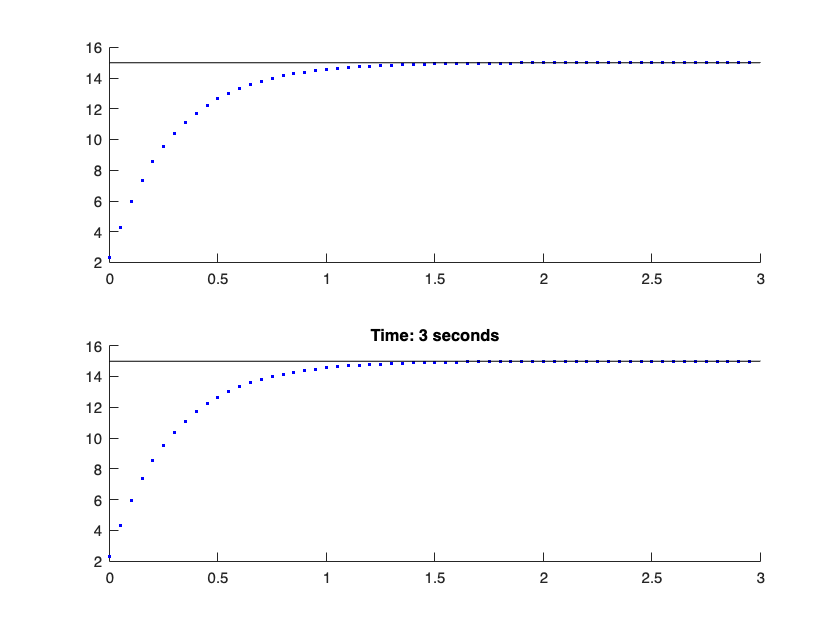

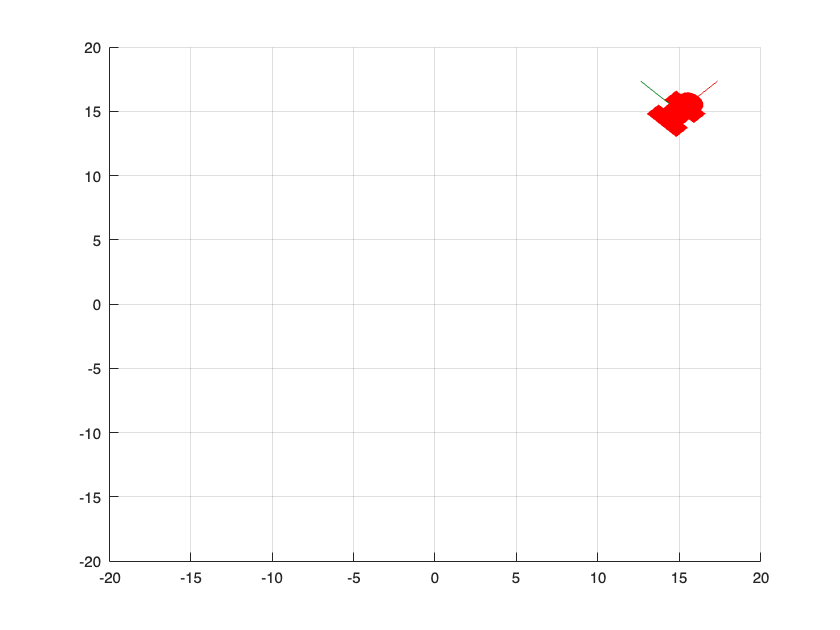

time = 0;
figure(2),clf
for i=1:(3/dT)  %run the simulation for a time equivalent to 3 seconds

    e_p_wf = p_des(1:2)-robotPose(1:2);

    psi = robotPose(3);

    v = k_v*( cos(psi)*e_p_wf(1)+sin(psi)*e_p_wf(2) );

    A = [1 -d/2;
         1  d/2];
    phi_des = 1/r*A*[v,0]';
    phiL = phi_des(1);
    phiR = phi_des(2);

    robotVelocity = derivative( robot,robotPose, [phiL,phiR] );
    robotPose = robotPose + dT*robotVelocity;

    t = [robotPose(1:2); 0];    %extract 2D position of robot
    q = [cos(robotPose(3)/2) 0 0 sin(robotPose(3)/2)]; %quaternion that encodes 1D orientation

    figure(1),clf,hold on
    axis([-20 20 -20 20]),grid on
    plotTransforms(t', q, "MeshFilePath", "groundvehicle.stl", "Parent", gca, "View","2D", "FrameSize", robot.TrackWidth/.3);
    plot(p_des(1),p_des(2),'ko',MarkerFaceColor='k')

    figure(2),hold on
    subplot(2,1,1),hold on,plot(time,t(1),'b.'),line([0 3],[p_des(1) p_des(1)],"color",'k')
    subplot(2,1,2),hold on,plot(time,t(2),'b.'),line([0 3],[p_des(2) p_des(2)],"color",'k')

    time = time+dT;
    title(['Time: ',num2str( time ), ' seconds'])
    % text(-18,18,{['Orientation error: ',num2str( e_psi*180/pi,'%.2f' ), ' deg a'], ...
    %              ['Position error norm: ',num2str( norm(e_p_wf),'%.2f' ), ' m']})

    drawnow
    waitfor(timer);
end

### 8.4.2 Orientation control

Unlike ${^Be_x}$ , ${^Be_y}$ is uncontrollable using $u_v$ , based on the slip-free model. We will instead resolve this error indirectly with an orientation controller. With reference to Figure 3, the *desired* orientation of our robot can be described using\footnote{Strictly speaking, we should use the *atan2* function, as the desired orientation can be anywhere in the interval $[-\pi,\pi)$ .} 


$$\begin{array}{cc}\psi^\ast = \tan^{-1}\frac{{^We_y}}{{^We_x}}.& \qquad (13)\\ \end{array}$$


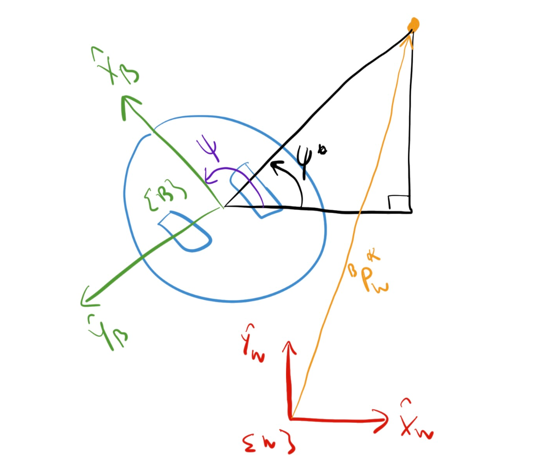

**Figure 3:** Resolving desired orientation from inertial-frame tracking error.
 

Equation \eqref{eq: theta ref} further demonstrates the coupled nature of the position and orientation in frame $\{W\}$ . Given a reliable measurement/estimate of the orientation, $\psi$ , we can define a proportional control law that acts on the rotational velocity on the robot body,


$$\begin{array}{cc}u_\omega = k_2\left( \psi^\ast-\psi \right) = k_2 \left( \tan^{-1}\frac{{^We_y}}{{^We_x}}-\psi \right),& \qquad (14)\\ \end{array}$$


where $k_2>0$ . As with $k_1$ , $k_2$ sets the bandwidth of the orientation controller, and will be limited by digital and saturation effects. The task of $u_\psi$ is to point the robot in the direction of the desired location. It makes physical sense to prioritise this control loop over the translational controller, as the robot can incur increasingly large errors if the robot is pointing in the wrong direction at the beginning of the manoeuvre. One could also artificially force the translational velocity controller to only take action once the orientation error is sufficiently small, or scale the proportional gain according to the inverse of the angular error. The position controller in \eqref{eq: Be_x} notably only considers errors in  $\hat{\mathbf x}_B$ , which inherently relies on the orientation controller pointing  $\hat{\mathbf x}_B$ in the direction of the target point in order for motion to proceed. In this configuration, the mobile robot will stop translating when  $\hat{\mathbf y}_B$ points at the target location, and will only recommence motion once the orientation is adjusted. This can result in conservative and disjointed motion depending on the controller gains selected and initial configuration of the robot. A more aggressive method to maintain continuous velocity is to rather use the Euclidean distance from the robot to the destination as an error signal, 


$$\begin{array}{cc}e_d = \sqrt{{^We_x^2}+{^We_y^2}}.& \qquad (15)\\ \end{array}$$


The corresponding position control law follows as 


$$\begin{array}{cc}u_v = k_1{e_d} = k_1 \sqrt{{^We_x^2}+{^We_y^2}}.& \qquad (16)\\ \end{array}$$


In this form, the mobile robot will continue to translate until such time that the distance to the target location reaches zero. While this can result in a more natural and fluid motion from the start to end points, there is the risk of never reaching the target location if the proportional gain of the position controller is set too aggressively relative to the orientation controller. The control law in \eqref{eq: u_v} is also applicable to mobile robots that have a car-like or bicycle model, where changing orientation is only possible when the robot is also experiencing a linear velocity.

## 8.5 Pure pursuit trajectory tracking 

We can extend our concept of point-to-point motion to the generalised case of following a trajectory. This trajectory can originate from a trajectory generation routine (see Chapter \ref{ch: traj. gen.}), or from real-time information based on the robot's sensors. The basic concept of a pure pursuit controller is to track a reference point on the trajectory that constantly moves in relation to the robot at a constant velocity. This can be likened to a donkey chasing after a carrot \cite{corke2017robotics}. With reference to Figure 4, our formulation of the problem follows on from \eqref{eq: e_d} in the previous section,


$$\begin{array}{cc}e_d = \sqrt{{^We_x^2}+{^We_y^2}} - d^\ast,& \qquad (17)\\ \end{array}$$


with the inclusion of a distance, $d^\ast$ , that corresponds to the desired displacement between the robot (donkey) and pursuit point (carrot). 

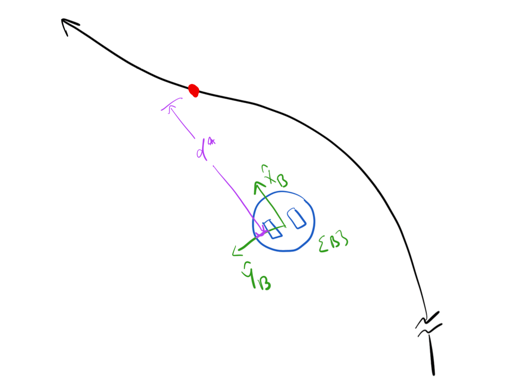

**Figure 4:** Robotic platform tracking a moving point using velocity control (pure pursuit).
 

The aim then is to force $e_d \rightarrow 0$ , which implies that $\sqrt{{^We_x^2}+{^We_y^2}} = d^\ast$ . That is, the Euclidean distance from the robot to the pursuit point is $d^\ast$ . Note that the constant offset while the robot is in motion implies that we are no longer controlling the position of our robot directly, but rather controlling the robot's velocity. To accommodate this change, we restructure our velocity controller as follows:


$$\begin{array}{cc}u_v = k_{v_1} e_d + k_{v_2} \int e_d dt,& \qquad (18)\\ \end{array}$$


which denotes a *PI* controller form with $k_{v_1}>0$ and $k_{v_2}>0$ . The integral term is required to provide a nonzero velocity command when the corresponding error, $e_d$ is zero. This is because we lost the integrator in our loop transfer function when we moved from a position control loop to a velocity control loop. The orientation controller remains unchanged and is repeated below for sake of convenience:


$$\begin{array}{cc}u_\psi = k_2\left( \psi^\ast-\psi \right) = k_2 \left( \tan^{-1}\frac{{^We_y}}{{^We_x}}-\psi \right),& \qquad (19)\\ \end{array}$$


where $k_2>0$ . The orientation controller fulfills a similar role as in the previous scenario, but depending on the variability in the specific trajectory, more control action will be required to continuously readjust the robot in order to face the pursuit point.